clear all;
close all;

## RO

prefix = "ro";
limit = 200;

raw_data = readmatrix(prefix+'_raw_'+string(limit)+'.csv');

[size_sample_raw, size_response_raw] = size(raw_data);
[~, ~, variances_raw, average_uniformity_raw, average_reliability_raw, ~, ~] = intra_device_analysis_fn(raw_data);


ecc_data = readmatrix(prefix+'_ecc_'+string(limit)+'.csv');
    
[size_sample_ecc, size_response_ecc] = size(ecc_data);
[~, ~, variances_ecc, average_uniformity_ecc, average_reliability_ecc, ~, ~] = intra_device_analysis_fn(ecc_data);


croped_data = raw_data(:,1:size_response_ecc);
    
[size_sample_raw_croped, size_response_raw_croped] = size(croped_data);
[~, ~, variances_raw_croped, average_uniformity_raw_croped, average_reliability_raw_croped, ~, ~] = intra_device_analysis_fn(croped_data);


### RAW

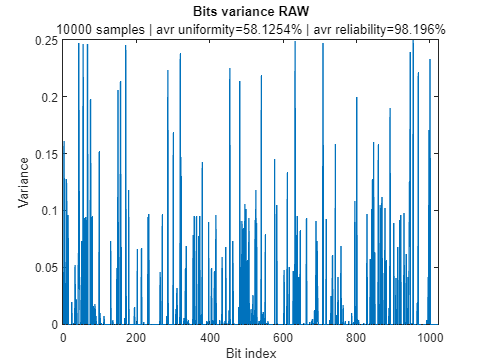

figure;
plot(1:size_response_raw, variances_raw)
xlabel("Bit index");
ylabel("Variance");
title("Bits variance RAW");
xlim([0 size_response_raw]);
subtitle(string(size_sample_raw)+" samples | avr uniformity="+string(average_uniformity_raw)+"% | avr reliability="+string(average_reliability_raw)+"%");

### RAW CROPED

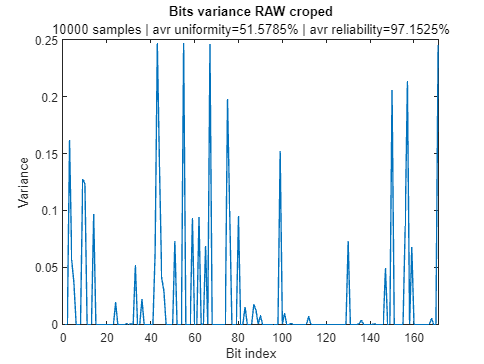

figure;
plot(1:size_response_raw_croped, variances_raw_croped)
xlabel("Bit index");
ylabel("Variance");
xlim([0 size_response_raw_croped]);
title("Bits variance RAW croped");
subtitle(string(size_sample_raw_croped)+" samples | avr uniformity="+string(average_uniformity_raw_croped)+"% | avr reliability="+string(average_reliability_raw_croped)+"%");

### ECC

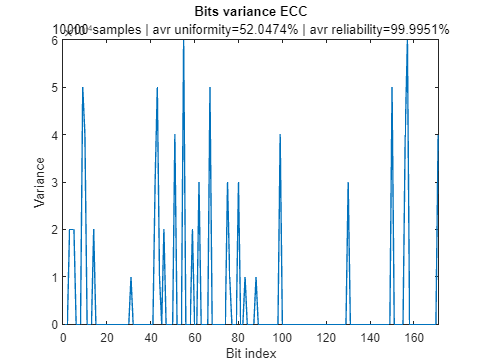

figure;
plot(1:size_response_ecc, variances_ecc)
xlabel("Bit index");
ylabel("Variance");
xlim([0 size_response_ecc]);
title("Bits variance ECC");
subtitle(string(size_sample_ecc)+" samples | avr uniformity="+string(average_uniformity_ecc)+"% | avr reliability="+string(average_reliability_ecc)+"%");

## TERO-8

prefix = "tero_8";
limit = 60;

raw_data = readmatrix(prefix+'_raw_'+string(limit)+'.csv');

[size_sample_raw, size_response_raw] = size(raw_data);
[~, ~, variances_raw, average_uniformity_raw, average_reliability_raw, ~, ~] = intra_device_analysis_fn(raw_data);

ecc_data = readmatrix(prefix+'_ecc_'+string(limit)+'.csv');
    
[size_sample_ecc, size_response_ecc] = size(ecc_data);
[~, ~, variances_ecc, average_uniformity_ecc, average_reliability_ecc, ~, ~] = intra_device_analysis_fn(ecc_data);

croped_data = raw_data(:,1:size_response_ecc);
    
[size_sample_raw_croped, size_response_raw_croped] = size(croped_data);
[~, ~, variances_raw_croped, average_uniformity_raw_croped, average_reliability_raw_croped, ~, hd_intra] = intra_device_analysis_fn(croped_data);


### RAW

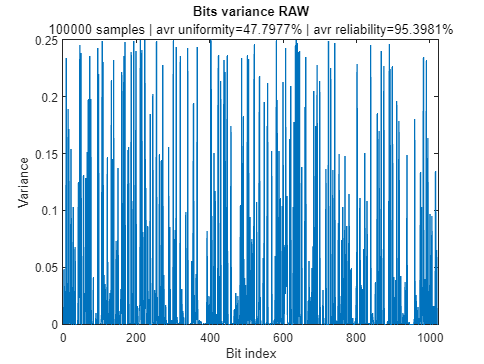

figure;
plot(1:size_response_raw, variances_raw)
xlabel("Bit index");
ylabel("Variance");
xlim([0 size_response_raw]);
title("Bits variance RAW");
subtitle(string(size_sample_raw)+" samples | avr uniformity="+string(average_uniformity_raw)+"% | avr reliability="+string(average_reliability_raw)+"%");

### RAW CROPED

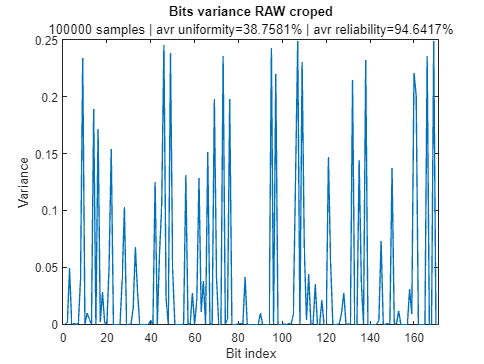

figure;
plot(1:size_response_raw_croped, variances_raw_croped)
xlabel("Bit index");
ylabel("Variance");
xlim([0 size_response_raw_croped]);
title("Bits variance RAW croped");
subtitle(string(size_sample_raw_croped)+" samples | avr uniformity="+string(average_uniformity_raw_croped)+"% | avr reliability="+string(average_reliability_raw_croped)+"%");

### ECC

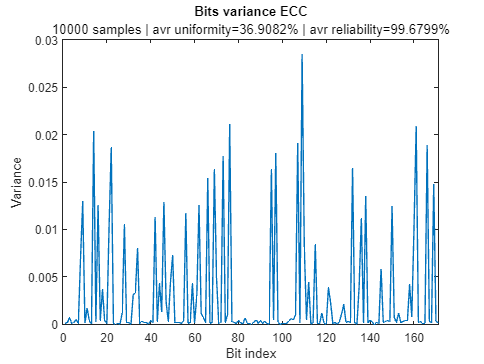

figure;
plot(1:size_response_ecc, variances_ecc)
xlabel("Bit index");
ylabel("Variance");
xlim([0 size_response_ecc]);
title("Bits variance ECC");
subtitle(string(size_sample_ecc)+" samples | avr uniformity="+string(average_uniformity_ecc)+"% | avr reliability="+string(average_reliability_ecc)+"%");